alpha = 1+ mod(235,3)

alpha = 2

% Q1 part1 
alpha = 1+ mod(235, 3);

% Time values
duration = 1 / alpha;
sampling_rate = 1000

sampling_rate = 1000

time = linspace(0, duration, duration * sampling_rate);

% Frequencies
freq_1 = 5 * alpha

freq_1 = 10

freq_2 = 6 * alpha

freq_2 = 12

freq_3 = 10 * alpha

freq_3 = 20

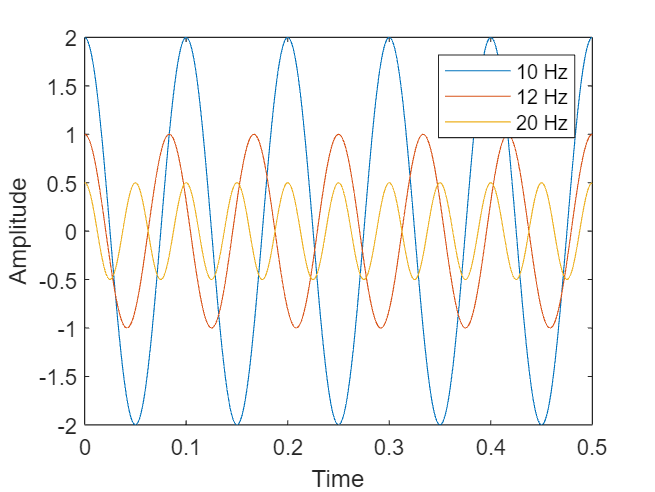


% Generate signals α
signal_1 = alpha * cos(2 * pi * freq_1 * time);
signal_2 = (alpha / 2) * cos(2 * pi * freq_2 * time);
signal_3 = (alpha / 4) * cos(2 * pi * freq_3 * time);

% Plot signals
figure;
plot(time, signal_1, 'DisplayName', sprintf('%d Hz', freq_1));
hold on;
plot(time, signal_2, 'DisplayName', sprintf('%d Hz', freq_2));
plot(time, signal_3, 'DisplayName', sprintf('%d Hz', freq_3));
xlabel('Time');
ylabel('Amplitude');
legend;
hold off;

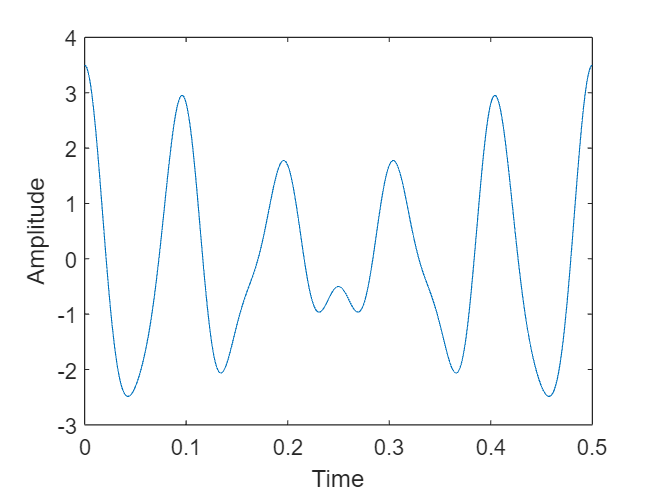

% question 1 part 2 
signal_4 = signal_1 + signal_2 + signal_3;
plot(time,signal_4)
xlabel('Time');
ylabel('Amplitude');

%question 1 part 3

time = linspace(0, duration, 1000*duration); % High-resolution time for accurate plotting

% Sampling frequencies
Fs_a = 14*alpha; % Fs = 14alpha samples/second
Fs_nyquist = 2 * max([freq_1, freq_2, freq_3]); % Nyquist rate
Fs_aliasing = 9*alpha; % Aliasing scenario

% Sample the cumulative signal at different sampling frequencies
samples_a = signal_4(1 : round(Fs_a*duration) : end)

samples_a =     3.5000    1.6676   -1.3633   -2.4848   -1.9579   -0.4661    1.8842    2.9095    0.8849   -1.6466   -1.8739   -0.9023   -0.1557    0.9697    1.7770    0.7279   -0.7778   -0.7913   -0.5176   -0.9386   -0.3675    1.2985    1.6597    0.5090   -0.4223   -1.2417   -2.0560   -0.9376    1.8785    2.8837    1.0342   -1.1275   -2.2574   -2.3433   -0.4061    2.6769


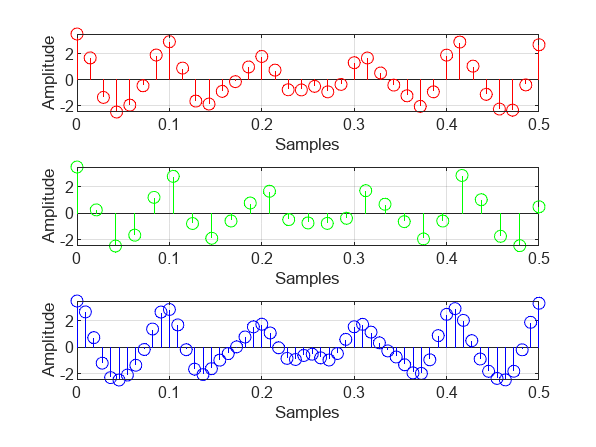

samples_nyquist = signal_4(1 : round(Fs_nyquist*duration): end);
samples_aliasing = signal_4(1 : round(Fs_aliasing*duration) : end);

% Discrete-time waveforms using stem
time_a = linspace(0, duration, length(samples_a));
time_nyquist = linspace(0, duration, length(samples_nyquist));
time_aliasing = linspace(0, duration, length(samples_aliasing));

% Plot discrete-time waveforms in subplots
figure;

subplot(3, 1, 1);
stem(time_a, samples_a,'r');
xlabel('Samples');
ylabel('Amplitude');
%title('Discrete-Time Waveform (Fs = 14alpha samples/second)');
grid on;

subplot(3, 1, 2);
stem(time_nyquist, samples_nyquist,'g');
xlabel('Samples');
ylabel('Amplitude');
%title('Discrete-Time Waveform (Nyquist Rate)');
grid on;

subplot(3, 1, 3);
stem(time_aliasing, samples_aliasing,'b');
xlabel('Samples');
ylabel('Amplitude');
%title('Aliasing');
grid on;

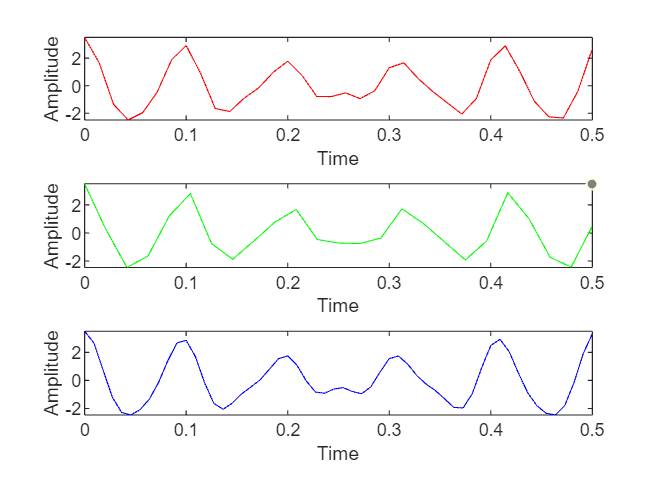

%question 1 part 4

% Plot interpolated signals
figure;

subplot(3, 1, 1);
plot(time_a, samples_a, 'r');
%title('Fs = 14\alpha samples/second');
xlabel('Time');
ylabel('Amplitude');

subplot(3, 1, 2);
plot(time_nyquist, samples_nyquist, 'g');
%title('Nyquist rate');
xlabel('Time');
ylabel('Amplitude');

subplot(3, 1, 3);
plot(time_aliasing, samples_aliasing, 'b');
%title('Linear Interpolation: Aliasing (6\alpha Hz aliased to 3\alpha Hz)');
xlabel('Time');
ylabel('Amplitude');

%Question2
a = 1 + mod(235,3);
f = [220,246.94,261.63,293.66,329.63,349.23,392,440]

f =   220.0000  246.9400  261.6300  293.6600  329.6300  349.2300  392.0000  440.0000


fs = 44000;
for freq=f
    t = 0:(1/fs):2;
    y = sin(2*pi*freq*t);
    %sound(y,fs);
    pause(1)
end
pause(2);
fs = 70000;
for freq=f;
    t = 0:(1/fs):2;
    y = sin(2*pi*freq*t);
    %sound(y,fs)
end
pause(2);
fs = 10000;
for freq=f
    t = 0:(1/fs):2;
    y = sin(2*pi*freq*t);
    sound(y,fs)
    pause(1)
end
%high sampling frequency gives a better audio quality but larger storage
%and faster converters. Low sampling frequency leads to low audio quality but
%easier storage and conversion.

%question 2
frequencies = [261.63, 293.66, 329.63, 349.23, 392.00, 440.00, 493.88, 523.25];

duration = 1.0;             % Duration of each note in seconds
sample_rate = 44100;        % Number of samples per second (standard for audio)

sequence = [];
new_sequence =[];

for freq = frequencies
    t = linspace(0, duration, duration * sample_rate);
    signal = sin(2 * pi * freq * t);
    sequence = [sequence, signal];
end
for i = 1 : 3 : length(sequence) 
    new_sequence = [new_sequence, signal];
end

output_file = 'melody.wav';
audiowrite(output_file, new_sequence, sample_rate);
data = audioread('melody.wav');
%sampling_rates = [44100, 22050, 11025]
sound(data,sampling_rate/3);

with a higher sampling rate, 44100 Hz for instance, the audio quality is better and its resemblance to the audio produced by a musical instrument is more. The sound is smoother and more accurate, especially for higher-pitched notes. 

When using lower sampling rates, 11025 Hz for example, some distorsion is observed, especially for higher-pitched notes. This distortion is known as "aliasing" and results from frequencies above the Nyquist frequency (half of the sampling rate) folding back into the audible range.

%question 3
[y, Fs] = audioread('Track002.wav');
%sound(y, Fs);
usampling_factors = [2, 3, 4]; 
sound(y,Fs/upsampling_factors(3))

%upsampling 


observations: 

Downsampling introduces aliasing, where high-frequency content above the Nyquist frequency gets folded back into the audible range. This causes the distortion in the higher frequency rainfall components in the audio. On decrease in sampling rate, high-frequency details are lost. There is also a loss of clarity in the downsampled audio and it sounds more muffled. 

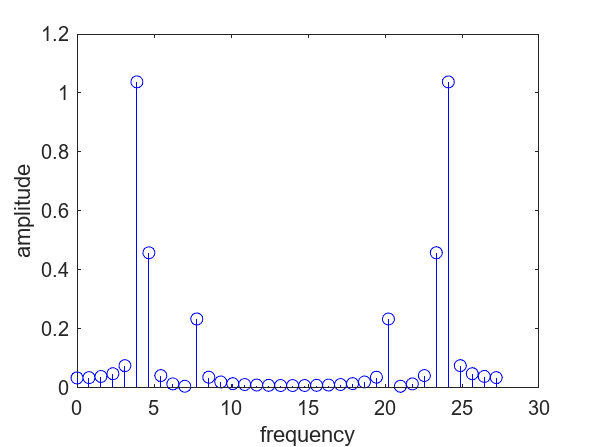

%1 part 5
Ta = 1/Fs_a;       
La = length(samples_a);
time_a = (0:La-1)*Ta;
Tn = 1/Fs_aliasing;       
Ln = length(samples_aliasing);
time_n = (0:Ln-1)*Tn;
y0 = fft(samples_a);
s0 = fft(samples_aliasing);
fa = Fs_a*(0:(La-1))/La;
fn = Fs_aliasing*(0:((Ln-1)))/Ln;
P2 = abs(y0/La);
P1 = P2(1:La/2+1);
P1(2:end-1) = 2*P1(2:end-1);
Q2 = abs(s0/Ln);
Q1 = Q2(1:Ln/2+1);
Q1(2:end-1) = 2*Q1(2:end-1);
figure;
stem(fa, P2,'blue');
xlabel('frequency')
ylabel('amplitude')

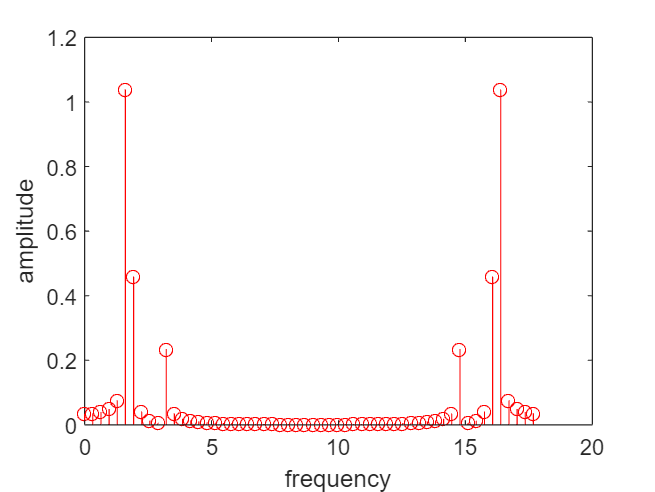

figure;
stem(fn, Q2,'red');
xlabel('frequency')
ylabel('amplitude')